## Import Geometry

ITO_geo =  createpde(1);
Well_geo = createpde(2);
WE_geo =   createpde(3);
CE_geo =   createpde(4);

importGeometry(ITO_geo,'ITO Slide.stl')

ans =   DiscreteGeometry with properties:

       NumCells: 1
       NumFaces: 6
       NumEdges: 12
    NumVertices: 8
       Vertices: [8×3 double]


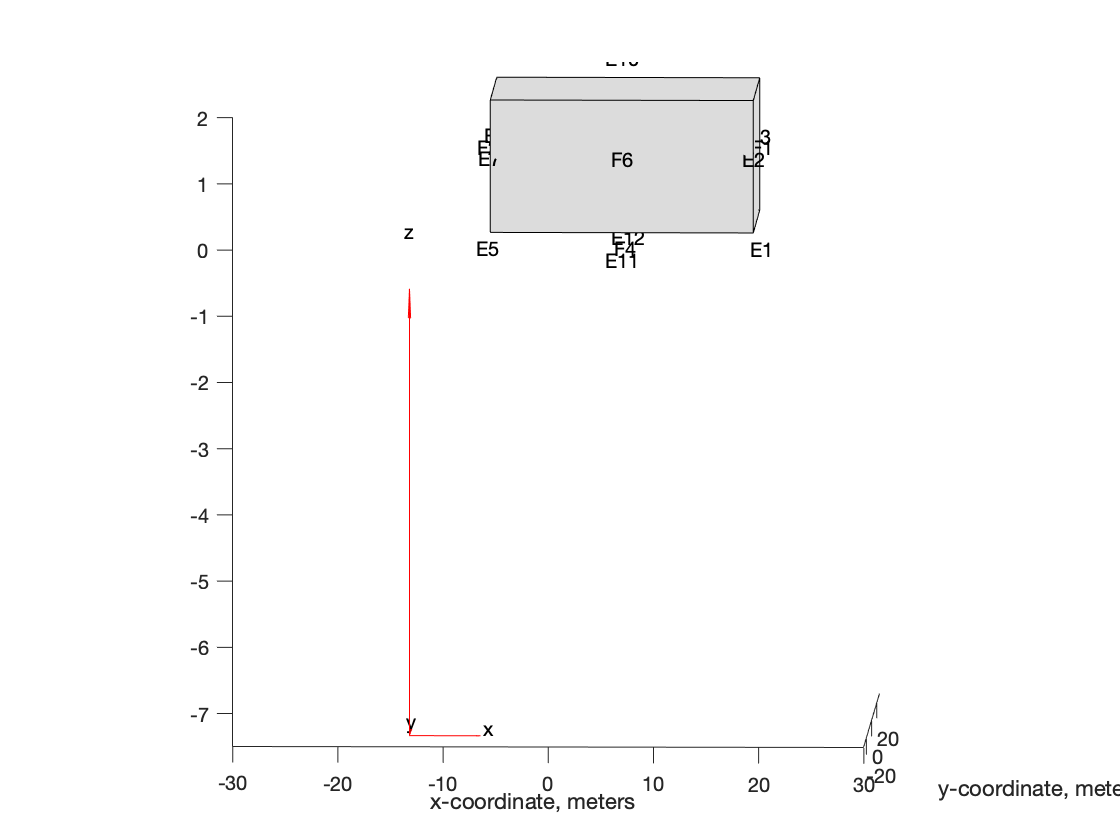

importGeometry(Well_geo,'Well.stl')
importGeometry(WE_geo,'ITO Slide.stl')
importGeometry(CE_geo,'ITO Slide.stl')

gd = [rect_domain,rect_movable,rect_fixed];

figure
pdegplot(myPde, "EdgeLabels","on", "FaceLabels","on")
xlabel('x-coordinate, meters')
ylabel('y-coordinate, meters')
axis([-30, 30,-30, 30])
axis square

## Specify PDE Coefficients

## Specify Boundary Conditions

## Mesh

%myPde.generateMesh("Hmax",0.25/2);
% Solve
% result = assempde(myPde,c,a,f);

## Visualize

%figure
%pdeplot3D(myPde,"ColorMapData",result);